# Loading the mnist dataset

[XTrain,YTrain,anglesTrain] = digitTrain4DArrayData;

# Selected  numbers to embed in the Hopfield network

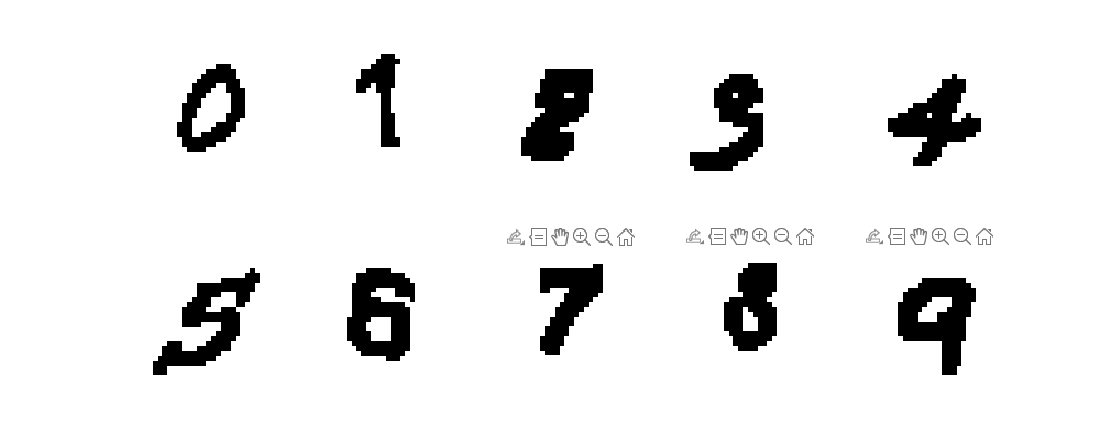

selected_numbers = 0:9; %% Change this list to increase number of memories you want to store

N = 28; N_tot = N*N;
N_mems = length(selected_numbers);
s_p = zeros(N_mems, N_tot);


fig = figure();
fig.Position(3:4) = 200* [5, 2];
counter = 1;
for i = selected_numbers
    data = XTrain(:, :, 1, (YTrain == num2str(i)) & (abs(anglesTrain) < 5));
    
    data = squeeze(data(:, :, randi(size(data, 4))));
    data = ~(data > 0);
    
    s_p(counter, :) = reshape(data, 1, N_tot);

    subplot(2, 5, counter)
    imshow(data)
    counter = counter + 1;
end

# Visualizing T matrix and checking Orthogonality of memories

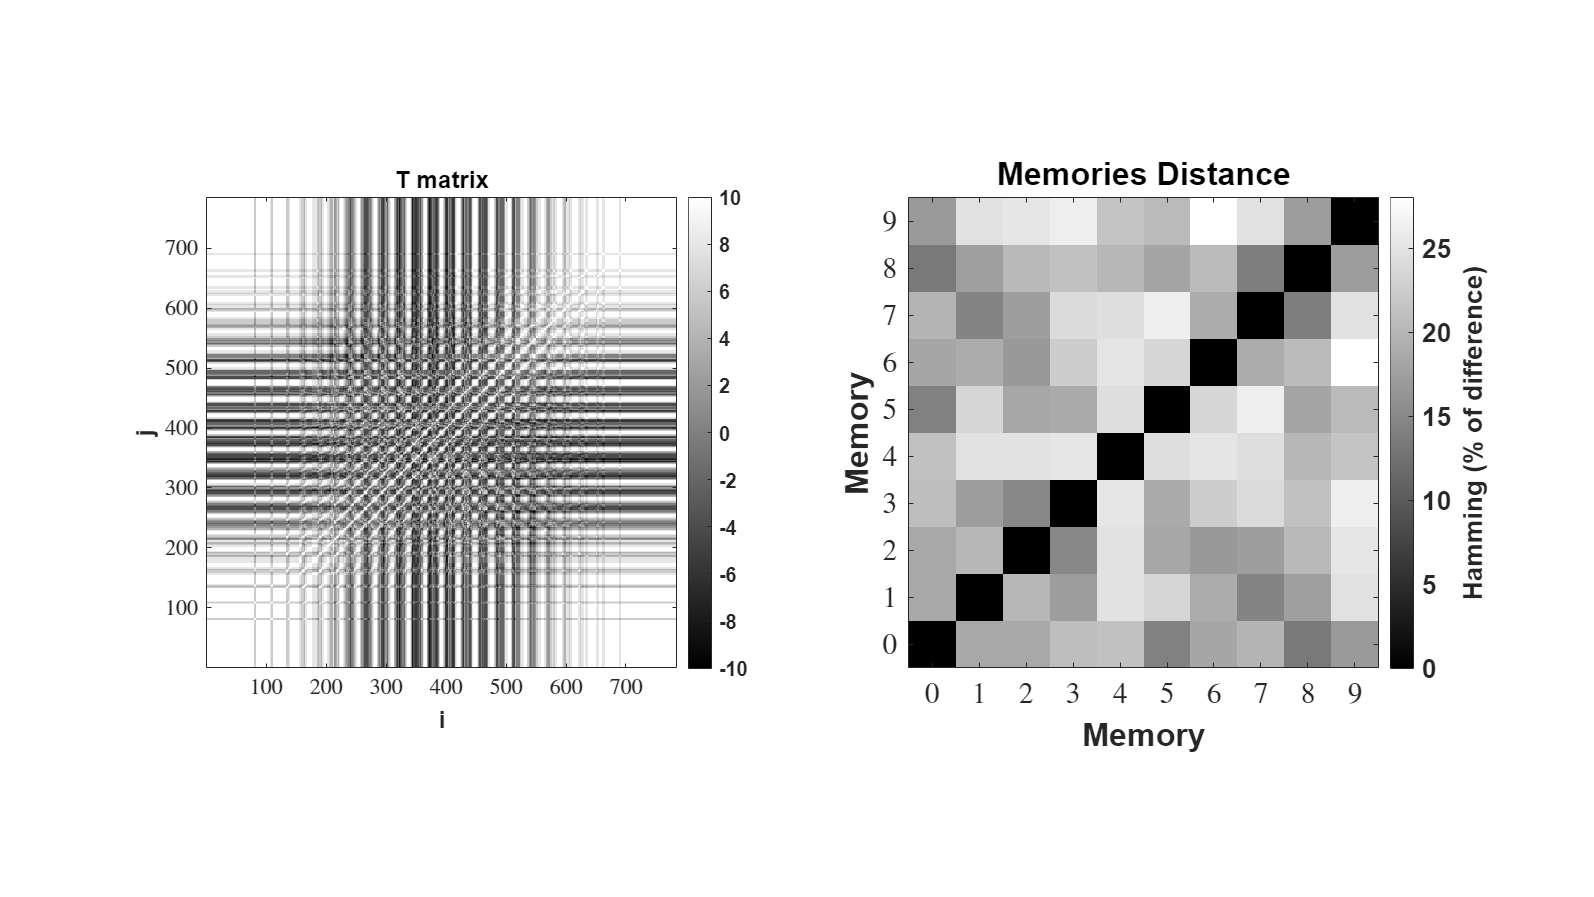

T = zeros(N_tot, N_tot);
for m = 1:N_mems
    T = T + (2*s_p(m, :)'-1)*(2*s_p(m,:)-1);
end

fig = figure();
fig.Position(3:4) = [1000 500];

subplot(1, 2, 1)

imagesc(T)
colormap("sky")
colorbar;
clim(N_mems* [-1 1]) 
set(gcf, 'Units', 'normalized', 'OuterPosition', [0 0 1 1]);
title("T matrix")
xlabel("i")
ylabel("j")
axis square
set(gca, 'YDir', 'normal', 'fontweight', 'bold', 'fontsize', 15); 

subplot(1, 2, 2)
imagesc(100*pdist2(s_p, s_p, 'hamming'))
title("Memories Distance")
colormap('gray')
cb = colorbar();
cb.Label.String = "Hamming (% of difference)";
axis square;
xticks(1:N_mems); yticks(1:N_mems)
xticklabels(selected_numbers)
yticklabels(selected_numbers)

xlabel("Memory")
ylabel("Memory")

drawnow;
set(gca, 'fontsize', 20, 'fontweight', 'bold', 'ydir', 'normal')

# Starting close to one of the numbers and see where the state converge

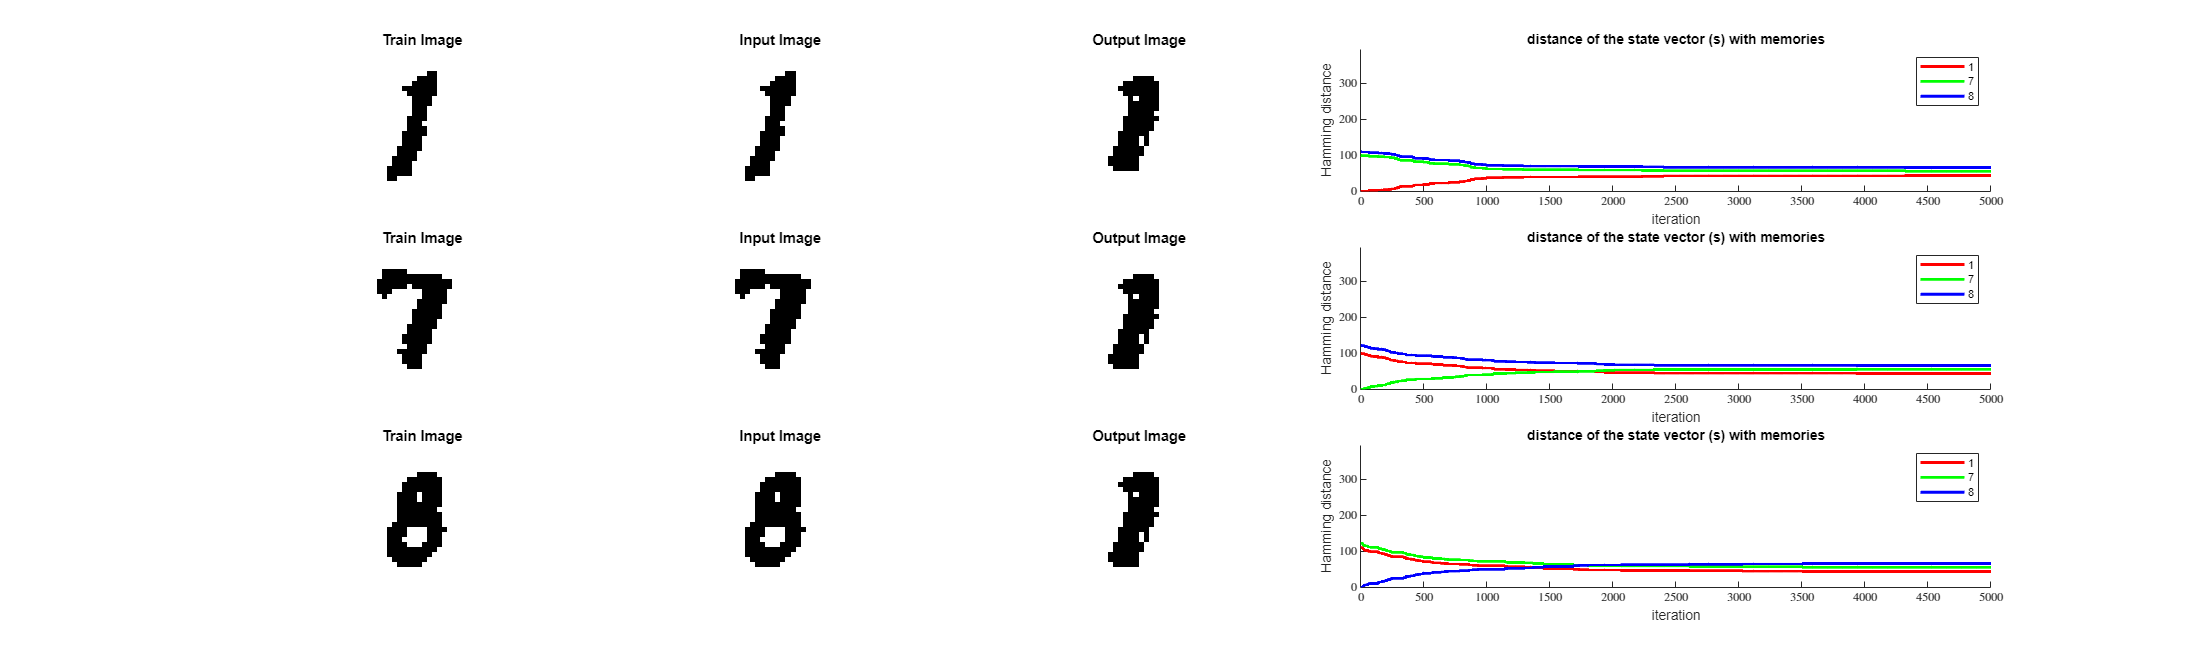

noisybits = 0; % Change the noise level to see how robust it is 

fig = figure();fig.Position(3:4) = 200*[10 N_mems];


for selected_mem = 1:N_mems
    s = s_p(selected_mem, :)';
    selectedbits = randi(N_tot, noisybits,1); %% Adding Noise
    s(selectedbits) = ~s(selectedbits);
    s0 = s;
    
    MAX_ITER = 5000;
    d = zeros(N_mems, MAX_ITER);
    for iter = 1:MAX_ITER
        
        temp = T*s > 0;
        selected_unit = randi(N_tot);
        s(selected_unit) = temp(selected_unit);
    
        for m = 1:N_mems
            diff = sum(s ~= s_p(m, :)');
            d(m, iter) = min(diff, N_tot-diff);
        end
    end
    
    cmap = hsv(N_mems);
    % cmap = cmap(randperm(N_mems), :);
    
    subplot(N_mems, 5, 5*(selected_mem-1)+[4, 5]); hold on;
    for m = 1:N_mems
        plot(d(m, :), '-', color = cmap(m, :),DisplayName=num2str(selected_numbers(m)), LineWidth=2)
    end
    
    legend()
    ylim([0 1+N_tot/2])
    xlabel("iteration")
    ylabel("Hamming distance")
    title("distance of the state vector (s) with memories")
    
    subplot(N_mems, 5, 1 + 5*(selected_mem-1))
    imshow(reshape(s_p(selected_mem, :), N, N))
    title("Train Image")

    subplot(N_mems, 5, 2 + 5*(selected_mem-1))
    imshow(reshape(s0, N, N))
    title("Input Image")
    
    subplot(N_mems, 5, 3 + 5*(selected_mem-1))
    imshow(reshape(s, N, N))
    title("Output Image")

    
end